# Group Assignment 11 

# Gender Study

# Girl or Boy?

### (LMa 131119)

You have a hypothesis that the gender of a child is dependant of the gender of previous born children. Data that could be used for this was summarised in a study from 2014:

[http://www.dst.dk/da/Statistik/NytHtml?cid=22535](http://www.dst.dk/da/Statistik/NytHtml?cid=22535)

Assume that the chance in the general population of having a girl is 48.5% and the chance of having a boy is 51.5%.

PrG = 0.485; 
PrB = 1 - PrG;

1. Find the data provided in the link, where the couple has previous had two boys (first row).

n_BB_b = 33694;
n_BB_g = 32193;

    a. What numbers would you get in an idealized experiment?

Not sure what is asked but i guess that it would be equal. Because we have the probabilities, we can calculate the total amount of each gender, because Prob = x/n

total_babies_BB = n_BB_g + n_BB_b;
format shortG;
EstN_BB_b = total_babies_BB * PrB

EstN_BB_b =         33932


EstN_BB_g = total_babies_BB * PrG

EstN_BB_g =         31955


b. What would the statistical model for this experiment be; if we test whether the gender of the third child is dependant on the genders of the two previous children?

x ~ binomial(N,PrB), PrG can also be used

c. Define the NULL hypothesis and the alternative Hypothesis.

NULL hypothesis:

estimated Probability of it being a boy B = PrB

alternative hypothesis:

estimated Probability of it not being a boy B  != PrB

d. Calculate the p-value based on a Binomial distribution.

First we have to get the difference bewtween the actual total amount of babies and the theoretical value

BB_b_difference = abs(n_BB_b - EstN_BB_b);

Now we use this formula 

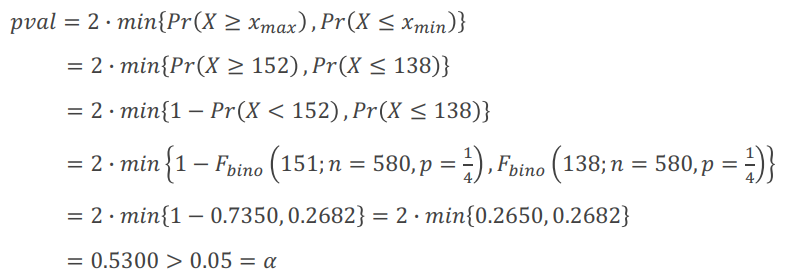

In matlab 

pr_lower_BB = binocdf((EstN_BB_b - BB_b_difference), total_babies_BB, PrB);
pr_upper_BB = 1 - binocdf((EstN_BB_b + BB_b_difference), total_babies_BB, PrB);
p_val_BB = 2 * min(pr_upper_BB, pr_upper_BB)

p_val_BB =      0.063886


=2 * min( Pr(x < mu - Dx), Pr(x > mu + Dx))

e. Can you with a significance level of 0.05, reject the NULL hypothesis?

Since pval > 0.05 we cannot reject the NULL hypothesis

f. Repeat the hypothesis test based on a normal approximation

z_BB = (n_BB_b - EstN_BB_b) / sqrt(EstN_BB_b * (1-PrB))

z_BB =       -1.8537


approx_p_val = 2 * abs(1 - normcdf(abs(z_BB)))

approx_p_val =      0.063778


although the p_val is a little less, the pval > 0.05 and therefore we cannot reject the NULL hypothesis

g. What is the estimator of p (“success”-rate), and what is the variance of the estimator?

p_est = PrB

p_est =         0.515


varp_est = PrB*(1-PrB)/total_babies_BB

varp_est =     3.791e-06


h. Calculate the confidence intervals for the p (“success”-rate) value.

The following formulas are used

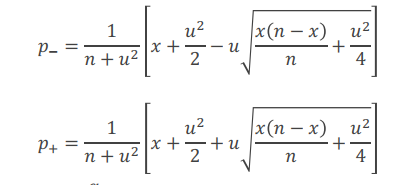

u = norminv(0.975);
last_part_form = u * sqrt((nB_BB * (total_babies_BB - nB_BB))/total_babies_BB + u^2 / 4);
p_min = 1/(total_babies_BB + u^2) * (nB_BB + (u^2)/2 - last_part_form)

p_min =       0.50757


p_plus = 1/(total_babies_BB + u^2) * (nB_BB + (u^2)/2 + last_part_form)

p_plus =       0.51521


barely within the interval

2. Make a Matlab script, which can make the hypothesis test for you

3. Repeat the hypothesis test for all the data from the link. Can you in any of the cases reject the hypothesis?

Write observed number of boys and girls

nB = [33694 26868 26741 28561 3615 2703 2708 2583 2644 2636 2646 3148 ...
      454 326 310 288 345 316 283 362 340 279 324 355 315 394 396 470];
nG = [32193 25264 25378 27068 3301 2593 2592 2517 2577 2552 2589 2928 ...
      429 324 309 285 337 292 290 352 302 280 278 348 300 345 360 420];
  
for i = 1 : length(nB)
   [N(i), EnB(i), z(i), pval(i), Rejecthypo(i)] = hypothesisTest(nB(i), nG(i)); 
end

pval =      0.063778


Rejecthypo = logical
   0


pval =       0.86073


Rejecthypo = logical
   0


pval =       0.37943


Rejecthypo = logical
   0


pval =       0.45567


Rejecthypo = logical
   0


pval =       0.20004


Rejecthypo = logical
   0


pval =        0.5016


Rejecthypo = logical
   0


pval =       0.55458


Rejecthypo = logical
   0


pval =       0.22292


Rejecthypo = logical
   0


pval =       0.21461


Rejecthypo = logical
   0


pval =       0.31971


Rejecthypo = logical
   0


pval =       0.16654


Rejecthypo = logical
   0


pval =        0.6283


Rejecthypo = logical
   0


pval =       0.95999


Rejecthypo = logical
   0


pval =       0.49226


Rejecthypo = logical
   0


pval =       0.47987


Rejecthypo = logical
   0


pval =       0.55314


Rejecthypo = logical
   0


pval =       0.63313


Rejecthypo = logical
   0


pval =       0.81521


Rejecthypo = logical
   0


pval =       0.31201


Rejecthypo = logical
   0


pval =       0.66896


Rejecthypo = logical
   0


pval =       0.45934


Rejecthypo = logical
   0


pval =       0.45209


Rejecthypo = logical
   0


pval =       0.25459


Rejecthypo = logical
   0


pval =       0.59497


Rejecthypo = logical
   0


pval =       0.88931


Rejecthypo = logical
   0


pval =       0.32345


Rejecthypo = logical
   0


pval =       0.62792


Rejecthypo = logical
   0


pval =       0.43459


Rejecthypo = logical
   0


    function [N, EnB, z, pval, Rejecthypo] = hypothesisTest(nbr_Guys, nbr_Girls)
        PrG = 0.485; 
        PrB = 1 - PrG;
        N = nbr_Guys + nbr_Girls;
        EnB = N * PrB;
        z = (nbr_Guys - EnB) / sqrt(N * PrB * (1 - PrB));
        pval = 2 * min(normcdf(z), 1 - normcdf(z))
        Rejecthypo = pval < 0.05
    end